# COL·LECCIÓ EXERCICIS

## ÀLGEBRA LINEAL NUMÈRICA

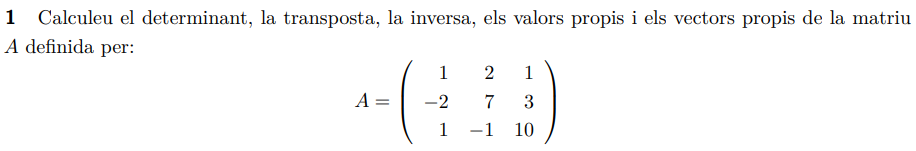

A = [1 2 1; -2 7 3; 1 -1 10];
determinant = det(A)
transposada = A'
inversa = inv(A)
[vectpropis, valpropis] = eig(A)

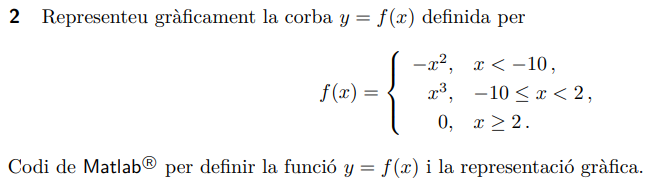

clearvars;
f = @(x) -x.^2.*(x < -10) + x.^3.* ((-10 <= x) & (x < 2)) + 0.*(x >= 2);
x = linspace(-20,20);
plot(x,f(x))

x = linspace(-6,6);
f = @(x) cos(x.^3./20);
plot(x,f(x)), xlabel('x'), ylabel('f(x)')

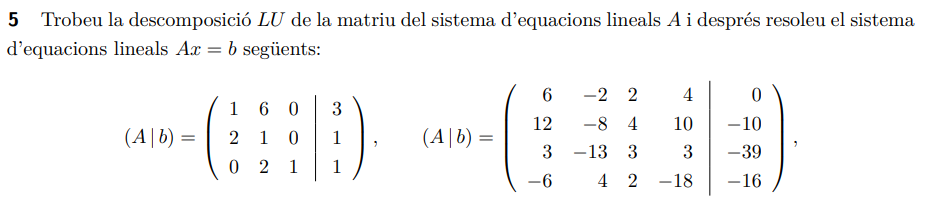

A = [1 6 0; 2 1 0; 0 2 1]; b = [3; 1; 1];
[L,U,P] = lu(A);
% comprovem PA = LU
norm(P*A-L*U,1)
% la solució del sistema és en dos etapes, primer resolem Ly=Pb i després Ux=y
y = linsolve(L,P*b); linsolve(U,y)  % linsolve més eficient
A = [6 -2 2 4; 12 -8 4 10; 3 -13 3 3; -6 4 2 -18]; b = [0; -10; -39; -16];
[L,U,P] = lu(A);
norm(P*A-L*U,1)
y = linsolve(L,P*b); linsolve(U,y)

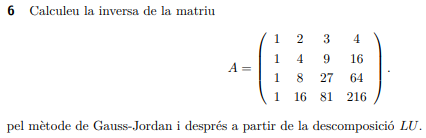

A = [1 2 3 4; 1 4 9 16; 1 8 27 64; 1 16 81 216];
% TODO Gauss-Jordan
inversa(A)

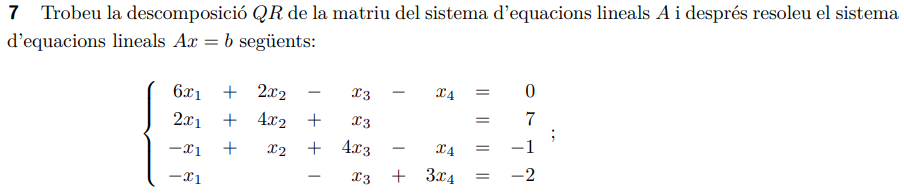

A = [6 2 -1 -1; 2 4 1 0; -1 1 4 -1; -1 0 -1 3]; b = [0; 7; -1; -2];
[Q,R] = qr(A);
% comprovem A = QR
prova = norm(A-Q*R,1)
% la solució del sisema és Rx = Q'b
linsolve(R,Q'*b)

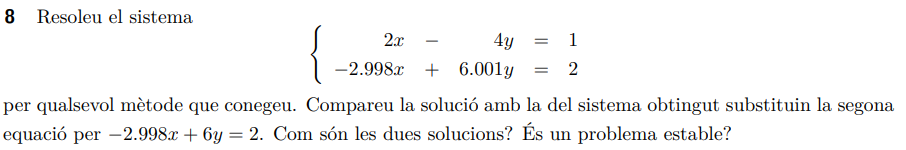

clearvars
A1 = [2 -4; -2.998 6.001]; b = [1; 2];
A2 = [2 -4; -2.998 6];
linsolve(A1,b), linsolve(A2,b)

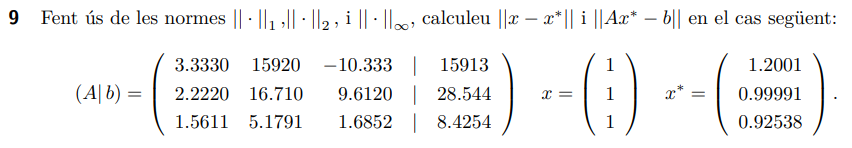

A = [3.3330 15920 -10.333; 2.2220 16.710 9.6120; 1.5611 5.1791 1.6852]; b = [15913; 28.544; 8.4254];
x = [1; 1; 1]; xa = [1.2001; 0.99991; 0.92538];

r1 = norm(x - xa, 1)        % norma 1
r2 = norm(x - xa, 2)        % norma 2
r3 = norm(x - xa, 'inf')    % norma màxim
r4 = norm(A*x-b, 1), r5 = norm(A*x-b, 2), r6 = norm(A*x-b,'inf')

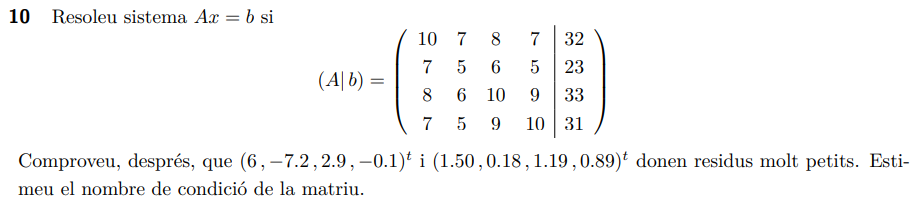

format shortG
A = [10 7 8 7; 7 5 6 5; 8 6 10 9; 7 5 9 10]; b = [32; 23; 33; 31];
x = linsolve(A,b);
fprintf('paràmetres de condicionament\n'), K = cond(A,1), RK = rcond(A)
b1 = [6, -7.2, 2.9, -0.1]';
b2 = [1.50, 0.18, 1.19, 0.89]';
B = [b1,b2],    x = A\B 
% aixo pasa perque els errors es propaguen
fprintf('vector residu\n'),rx = A*x-B
prediccio = K*norm(b1-b2,1)/norm(b1,1)*100
valor = norm(x(:,1)-x(:,2),1)/norm(x(:,1),1)*100

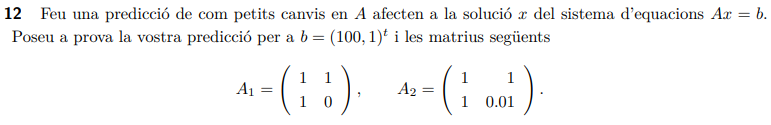

A1 = [1 1; 1 0]; A2 = [1 1; 1 0.01];
c1 = [cond(A1,1), cond(A1,2), cond(A1,'inf')]
c2 = [cond(A2,1), cond(A2,2), cond(A2,'inf')]
b = [100 1]';
x1 = linsolve(A1,b)
x2 = linsolve(A2,b)
norm(x1-x2,1)/norm(x1,1)*100
K = cond(A1,1), K2 = cond(A2,1)
prediccio = K*norm(A1-A2,1)/norm(A1,1)*100

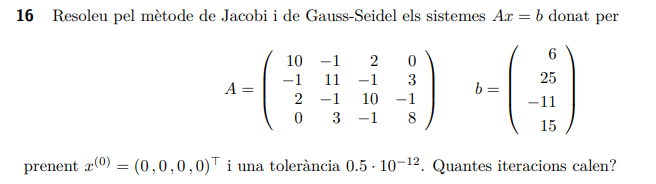

A = [10 -1 2  0; -1  11 -1 3; 2 -1 10 -1; 0 3 -1 8];
b = [6 25 -11 15]';
D = diag(diag(A)); 
L = tril(A-D); 
U = triu(A-D);

Mètode Jacobi

DI = inv(D);
BJ =-DI*(L+U);
cJ = DI*b;
rhoJ = abs(eigs(BJ,1))

rhoJ = 0.4264

n = 100;
if rhoJ < 1
    k = 0;
    x = zeros(size(b)); y = x;
    r = norm(A*x-b,1);
    e = zeros(n,1);
    d = e;
    while (k < n && r > 0.5e-12)
        k = k+1;
        x = BJ*x + cJ;
        e(k) = norm(x-y,1);
        if k ~= 1 
            d(k) = e(k)/e(k-1);
        end
        y = x;
        r = norm(A*x-b,1);
    end
    fprintf('El mètode és convergent, en k = %d, el residu és %5.4g i el vector solució és:\n',k,r)
    x
else
    fprintf('mètode de Jacobi divergent')
end

El mètode és convergent, en k = 38, el residu és 4.459e-13 i el vector solució és:


x =     1.0000
    2.0000
   -1.0000
    1.0000


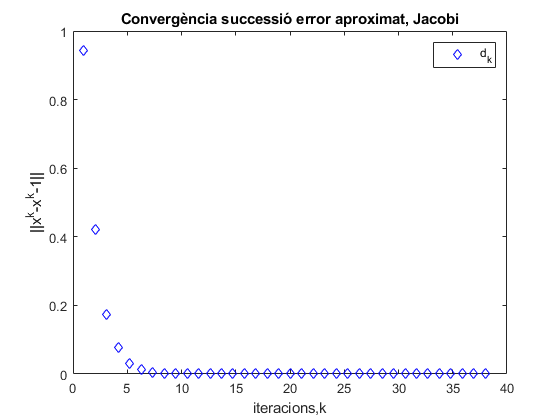

e = e(3:k); x_coord = linspace(1,k,k-2);
plot(x_coord,e,'bd');
title('Convergència successió error aproximat, Jacobi');
xlabel('iteracions,k'); ylabel('||x^k-x^k-1||');
yticks(0:0.2:1); legend('d_k');

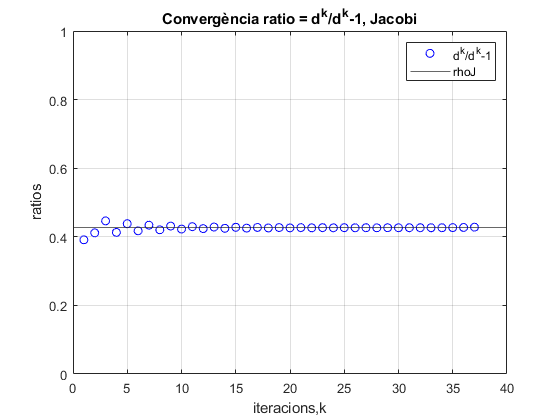

d = d(2:k); x_coord = linspace(1,k-1,k-1);
plot(x_coord,d,'bo');
grid on
title('Convergència ratio = d^k/d^k-1, Jacobi');
xlabel('iteracions,k'); ylabel('ratios');
yline(rhoJ); ylim([0 1]); yticks(0:0.2:1); 
legend('d^k/d^k-1','rhoJ');

Mètode Gauss-Seidel

format
DI = inv(D+L);
Bgs = -DI*U;
cgs = DI*b;
rhoGS = abs(eigs(Bgs,1))

rhoGS = 0.0898

if rhoGS < 1
    k = 0;
    x = zeros(size(b)); y = x;
    r = norm(A*x-b,1);
    e = zeros(n,1);
    d = e;
    while (k < n && r > 5e-12)
        k = k + 1;
        x = Bgs*x + cgs;
        e(k) = norm(x-y,1);
        if k ~= 1 
            d(k) = e(k)/e(k-1);
        end
        y = x;
        r = norm(A*x-b,1);
    end
    fprintf('El mètode és convergent, en k = %d, el residu és %5.4g i el vector solució és:\n',k,r)
    x
else
    fprintf('mètode de Gauss-Seidel divergent')    
end

El mètode és convergent, en k = 13, el residu és 4.572e-12 i el vector solució és:


x =     1.0000
    2.0000
   -1.0000
    1.0000


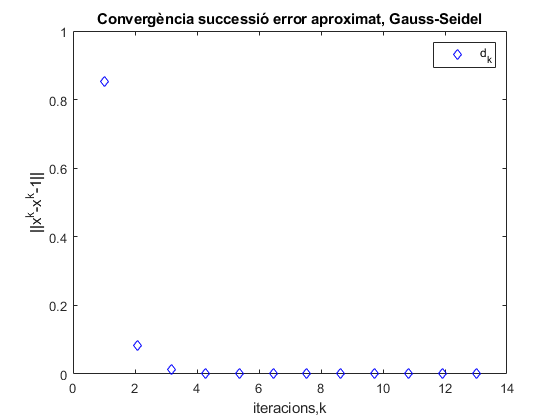


e = e(2:k);
x_coord = linspace(1,k,k-1);
plot(x_coord,e,'bd');
title('Convergència successió error aproximat, Gauss-Seidel');
xlabel('iteracions,k'); ylabel('||x^k-x^k-1||');
yticks(0:0.2:1), ylim([0 1]);
legend('d_k');

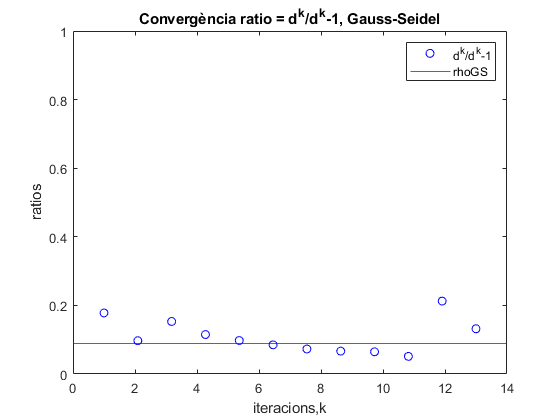

d = d(2:k); x_coord = linspace(1,k,k-1);
plot(x_coord,d,'bo');
title('Convergència ratio = d^k/d^k-1, Gauss-Seidel');
xlabel('iteracions,k'); ylabel('ratios');
yline(rhoGS); ylim([0 1]); yticks(0:0.2:1); 
legend('d^k/d^k-1','rhoGS');

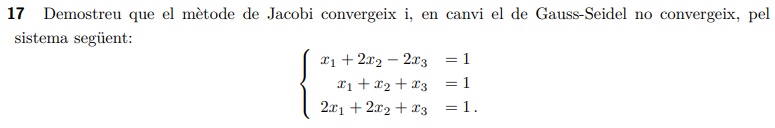

A = [1 2 -2; 1 1 1; 2 2 1]; b = [1; 1; 1];
jacobifun(A,b)

El mètode és convergent, en k = 3, el residu és     0 i el vector solució és:


ans =     -3
     3
     1


gseidelfun(A,b)

mètode de Gauss-Seidel divergent

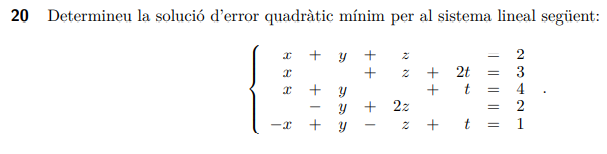

`Exercici 1`` Escriviu A i b i calculeu rang(A).`

A = [1 1 1 0; 1 0 1 2; 1 1 0 1; 0 -1 2 0; -1 1 -1 1]; b = [2; 3; 4; 2; 1];
rA = rank(A), rA == rank([A,b]) % Sistema d'equacions incompatible

rA = 4

ans = logical
   0


`Exercici 2`` Calcula `$A^tA$`, rang(`$A^tA$`) , det(`$A^tA$`)  i comproba que el sistema `${A^tAx=A^tb}$` és compatible determinat.`

B = A'*A

B =      4     1     3     2
     1     4    -2     2
     3    -2     7     1
     2     2     1     6


rB = rank(B)

rB = 4

d = det(B)

d = 175

rBM = rank([B,A'*b])

rBM = 4

compatible = (rB == rBM)  % Sistema d'equacions compatible determinat

compatible = logical
   1


`Exercici 3`` Calcula `$x=(x_1,x_2,\cdots,x_n)^t$`  solució del sistema `${A^tAx=A^tb}$`. `

x = linsolve(B, A'*b), X = lsqminnorm(A,b)

x =     0.1429
    1.2857
    1.2857
    1.1429


X =     0.1429
    1.2857
    1.2857
    1.1429


`Exercici 4`` Calculeu el vector residu en la solució. Comproveu que `$y=(0,-1,2,-1)^t$`  té residu més gran, es a dir la solució compleix la propietat de `$\min_{x}(\, {\bf r}^2\, )$`. `

rx = norm(b-A*x,2)

rx = 1.8898

ry = norm(b-A*[0;-1;2;-1],2)

ry = 8.9443

y = rand(size(x)); ry2 = norm(b-A*y,2), minim_cert_fals = (rx < ry2)

ry2 = 3.6561

minim_cert_fals = logical
   1


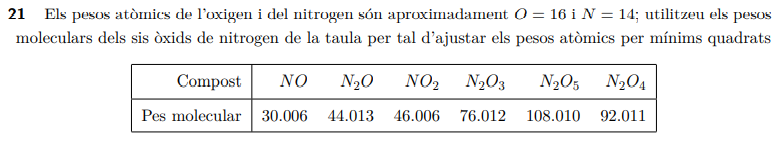

`Exercici 1`` Escriviu A i b i calculeu rang(A), enunciat associat a la pràctica 5`

A = [[1 2 1 2 2 2]',[1 1 2 3 5 4]']

A =      1     1
     2     1
     1     2
     2     3
     2     5
     2     4


b = [30.006 44.013 46.006 76.012 108.010 92.011]'

b =    30.0060
   44.0130
   46.0060
   76.0120
  108.0100
   92.0110


rA = rank(A), rA == rank([A,b]) % Sistema d'equacions incompatible

rA = 2

ans = logical
   0


`Exercici 2`` Calcula `$A^tA$`, rang(`$A^tA$`) , det(`$A^tA$`)  i comproba que el sistema `${A^tAx=A^tb}$` és compatible determinat.`

B = A'*A

B =     18    29
    29    56


rB = rank(B)

rB = 2

d = det(B)

d = 167.0000

rBM = rank([B,A'*b])

rBM = 2

compatible = (rB == rBM)

compatible = logical
   1


`Exercici 3`` Calcula `$x=(x_1,x_2,\cdots,x_n)^t$`  solució del sistema `${A^tAx=A^tb}$`. `

x = linsolve(B, A'*b)

x =    14.0069
   15.9993


`Exercici 4``  Calculeu el vector residu en la solució. Comproveu que `$O=16$` i `$N=14$` té residu més gran, es a dir la solució compleix la propietat de `$\min_{x}(\, {\bf r}^2\, )$`. `

rx = norm(b-A*x,2)

rx = 6.9213e-04

ry = norm(b-A*[14;16],2)

ry = 0.0246

minim_cert_fals = (rx < ry)

minim_cert_fals = logical
   1


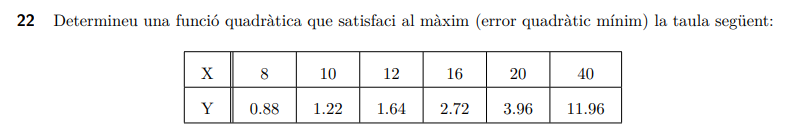

`Exercici 1`` Escriviu el sistema lineal associat al problema,  Ax=b, explícita A, b i rang(A).`

X = [8 10 12 16 20 40]';
A = [X.^2, X, ones(size(X))]

A =           64           8           1
         100          10           1
         144          12           1
         256          16           1
         400          20           1
        1600          40           1


b = [0.88 1.22 1.64 2.72 3.96 11.96]', Y = b;

b =     0.8800
    1.2200
    1.6400
    2.7200
    3.9600
   11.9600


rA = rank(A), rA == rank([A,b]) % Sistema d'equacions incompatible

rA = 3

ans = logical
   0


`Exercici 2`` Calcula `$A^tA$`, rang(`$A^tA$`) , det(`$A^tA$`)  i comproba que el sistema `${A^tAx=A^tb}$` és compatible determinat.`

B = A'*A

B =      2820368       79336        2564
       79336        2564         106
        2564         106           6


rB = rank(B)

rB = 3

d = det(B)

d = 2.0221e+08

rBM = rank([B,A'*b])

rBM = 3

compatible = (rB == rBM)

compatible = logical
   1


`Exercici 3`` Calcula `$x=(x_1,x_2,\cdots,x_n)^t$`  solució del sistema `${A^tAx=A^tb}$`. `

x = linsolve(B, A'*b), x = lsqminnorm(A,b)

x =     0.0045
    0.1307
   -0.5166


x =     0.0045
    0.1307
   -0.5166


`Exercici 4`` Representeu les dades i la funció quadràtica obtinguda en un mateix gràfic. `

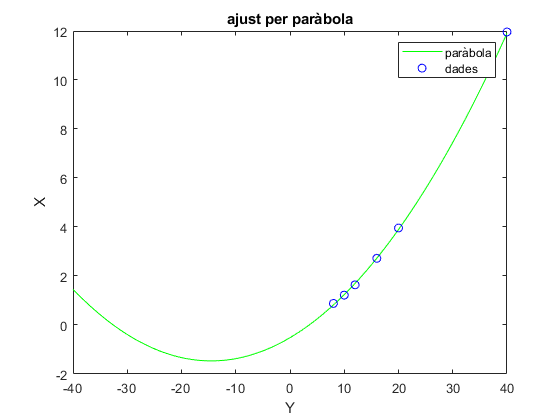

x = linspace(-40,40);
plot(x, 0.0045*x.^2+0.1307*x-0.5166,'g')
hold on
plot(X,Y,'bo')
hold off
title('ajust per paràbola');
xlabel('Y'); ylabel('X');
legend('paràbola','dades')

### D'EXAMEN

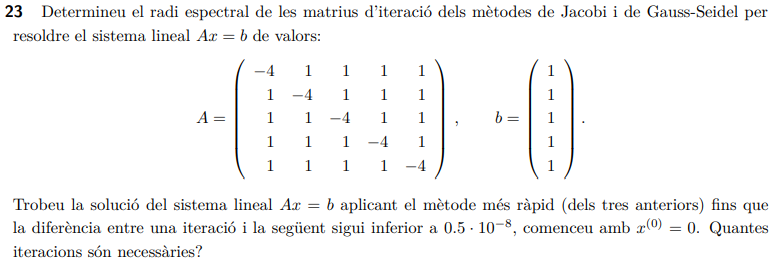

A = [-4 1 1 1 1; 1 -4 1 1 1; 1 1 -4 1 1; 1 1 1 -4 1; 1 1 1 1 -4]; b = [1 1 1 1 1]';
tol = 0.5e-8;
n = 50;
jacobifun(A,b,tol,n)

El mètode és convergent, en k = 50, el residu és     5 i el vector solució és:


ans =   -12.5000
  -12.5000
  -12.5000
  -12.5000
  -12.5000


gseidelfun(A,b,tol,50)

El mètode és convergent, en k = 50, el residu és     5 i el vector solució és:


ans =   -24.7000
  -24.8000
  -24.9000
  -25.0000
  -25.1000


%% Iteracions infinites, la diferència d'iteracions mai serà inferior a 0.5e-8